# A Discrete Cell Division Model - Part II

**During this assignment, you will pracitice the following: **

**Mathematical skills:** difference equations, discrete modeling, power and exponentials, equivalence of operations

**Coding skills**: for loops, plots, vectors, assigning values, indexing

**Step 1: Go through this example. Feel free to play with the code and see what happens! **

**Step 2: Answer the questions at the 'Questions 2' section at the bottom of this guide in a group **

## Intro 

One model to explain cell population uses *discrete steps* and the concept of *daughter* cells. At each step, the cells simultaneously divide into $b$ daughter cells. In part 1, we used for loops to calculate the final number of cells. We now try to use an equation in terms of `M0,n, `and `b` that calculates `Mn`.

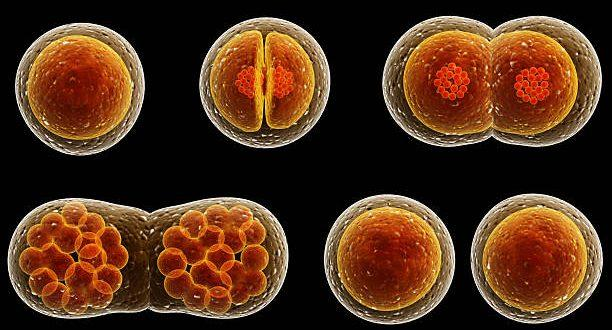

source: *https://mysciencesquad.weebly.com/16-cell-division.html*

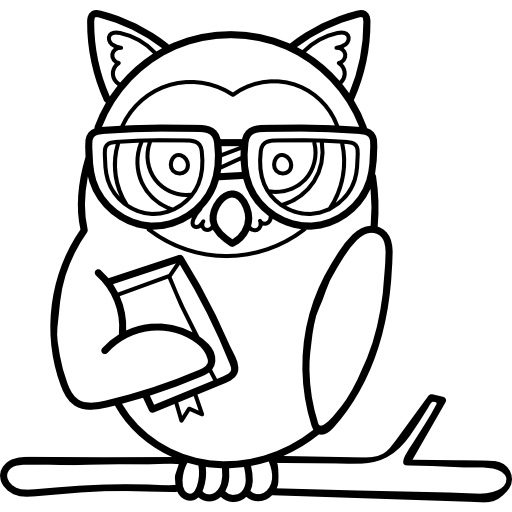  You can edit the blank fields!

## Code

Assign the number of initial cells M0, 

M0 = 1;

Choose the number of generations `n` 

n =4;

and the number of daughter cells `b` at each step:

b = 5;

We create `M`, a place-holder vector that keeps a history of the cell population:

M = ones(1,n);

We also create a vector that counts up to the generation of our interest:

Generation = linspace(0,n,n+1);

By multiplying the population number at each generation with `b, `the number of cells that each cell divides into, we can calculate the population number right after the division:

M(1) = M0*b;

M =      5     1     1     1


Now, we try two methods of getting to the answer.

#### Method 1: For Loops

Use a loop to create cells at each step

for k = 1:1:n-1
    M(k+1) = b*M(k); % at each step, we multiply the number of cells by b!
end

#### Method 2: Difference Equation

Use the following equation:

$M_n =M_0 {\left(b\right)}^n$                                                      Equation 1

The *function* below, uses Equation 1 to calculate $M_n$:

Mn = MnCalculator(M0, b,n) 

Mn = 625

## Graphs

Visualization of data usually helps us better understand it. Here, we graph the population number at each generation as a function of the generation:

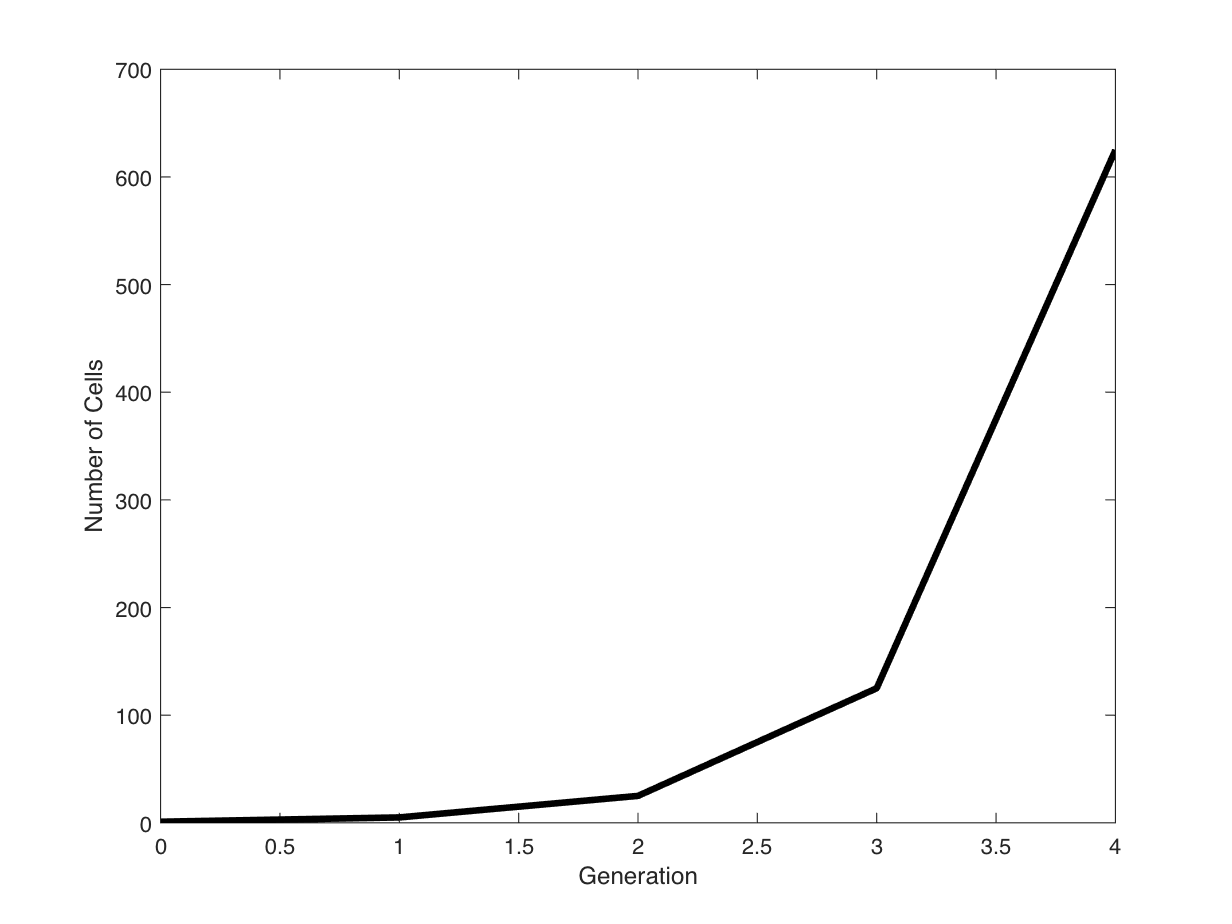

figure(2)
plot(Generation,[M0 M], 'LineWidth', 3, 'Color','k')
xlabel('Generation')
ylabel('Number of Cells')

## Questions Part 2

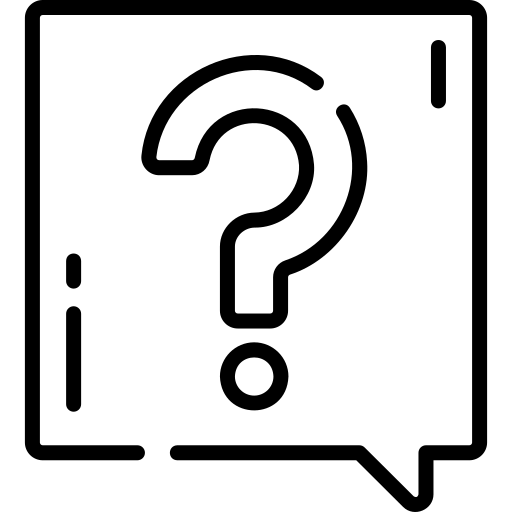 **Question 1:** Double check that the answer you get from the two methods agree by trying different values for `M0,n, `and `b.`

**Method 1:**

M(end)

ans = 625

**Method 2:**

Mn

Mn = 625

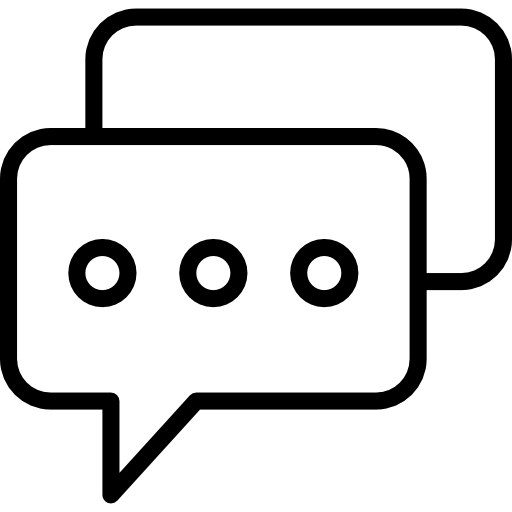 **Question 2:** The second method feels like a shortcut! Why do you think it works?

 **Question 3:** Will the number of cells always increase after each generation?

 **Question 4**: Remember the card game that we played in class? What would `M0,n, `and `b `represent in that scenario?

## Modeling Functions

function Mn = MnCalculator(M0,b,n)

Mn = M0*b^n;

end